%Ce code permet d'implémenter un cas de classification en utilisant

%l'algorithme de KNN

%Chargeons les données traitées à partir du fichier. nous  pouvons changer le chemin d'accès apres le télécargement  du dossier du code  

load C:\Users\Gbadessi\Downloads\machinelearning_course_files\letterfeatures.mat

%Ajustons, prévoyons et évaluons. Essayons un kNN simple.

kNNmodel = fitcknn(traindata,"Character")

kNNmodel =   ClassificationKNN
           PredictorNames: {1×25 cell}
             ResponseName: 'Character'
    CategoricalPredictors: []
               ClassNames: [A    B    C    D    E    F    G    H    I    J    K    L    M    N    O    P    Q    R    S    T    U    V    W    X    Y    Z]
           ScoreTransform: 'none'
          NumObservations: 2906
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


%Évaluons le modèle sur les données de test.

loss(kNNmodel,testdata)

ans = 0.2248

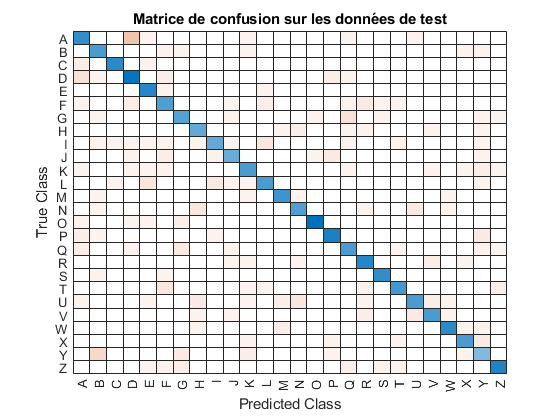

predLetter = predict(kNNmodel,testdata);
confusionchart(testdata.Character,predLetter); title('Matrice de confusion sur les données de test')

%Essayons plus de voisins. Étant donné que kNN est basé sur la distance, ajoutons la normalisation.

kNNmodel = fitcknn(traindata,"Character","NumNeighbors",10,"Standardize",true);
loss(kNNmodel,testdata)

ans = 0.1964

% Essayons un nombre différent de voisines, mais ajoutons une pondération en fonction de la distance.

kNNmodel = fitcknn(traindata,"Character","NumNeighbors",15,"Standardize",true, ...
    "DistanceWeight","squaredinverse");
loss(kNNmodel,testdata)

ans = 0.1808

% Essayons une approche différente : un ensemble d’arbres en sacs.

rng(123)
TBmodel = fitcensemble(traindata,"Character","Method","Bag","Learners","tree","NumLearningCycles",30);
loss(TBmodel,testdata)

ans = 0.1407

% On dirait que c’est à peu près aussi bon que ça va l’être. Revenons au modèle kNN pondéré avec k = 5.

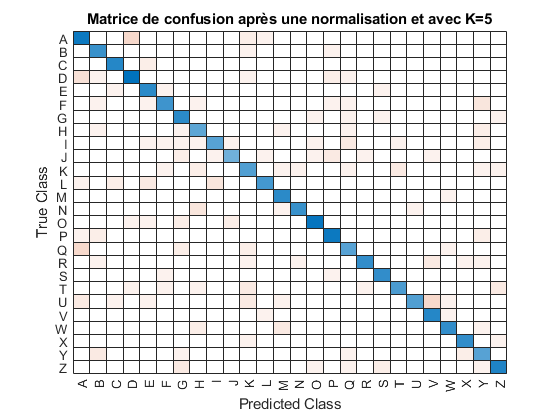

predLetter = predict(kNNmodel,testdata);
confusionchart(testdata.Character,predLetter); title('Matrice de confusion après une normalisation et avec K=5')

% Analysons les erreurs de classification

% Obtenons tout d'abord les données de la matrice de confusion.

cm = confusionmat(testdata.Character,predLetter);

% Fractionnons en classifications correctes et incorrectes

yes = diag(cm);
no = cm - diag(yes);

% Obtenir un taux d’erreur de classification pour chaque lettre.

misratebyletter = sum(no,2)./sum(cm,2);

% Convertissons en un tableau avec des noms de lettres et un taux d’erreur de classification.

letters = categories(traindata.Character);
misratebyletter = table(letters,misratebyletter,'VariableNames',["Letter","MisClassRate"]);

% Trions par pire erreur de classification

misratebyletter = sortrows(misratebyletter,"MisClassRate","descend")

misratebyletter = 26×2 table
    Letter    MisClassRate
    ______    ____________

    {'U'}       0.39535   
    {'I'}       0.32432   
    {'Q'}       0.32432   
    {'J'}       0.32258   
    {'K'}        0.2973   
    {'T'}       0.27027   
    {'L'}       0.26316   
    {'F'}       0.23684   
    {'Y'}       0.21875   
    {'A'}       0.21277   
    {'R'}       0.20513   
    {'D'}       0.20408   
    {'H'}           0.2   
    {'Z'}       0.19048   
    {'N'}       0.16667   
    {'W'}       0.16216   


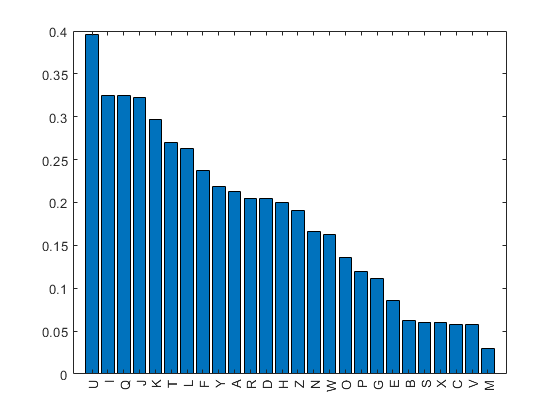

bar(misratebyletter.MisClassRate)
xticks(1:26)
xticklabels(misratebyletter.Letter)

% Regardons des exemples individuels de classification erronée.

letter = "A";

%Obtenons les observations avec cette classe réelle qui ont été mal classées comme quelque chose d’autre.

misclassidx = (testdata.Character == letter) & (predLetter ~= testdata.Character);

%Faisons un tableau des observations mal classées, avec la lettre prévue incluse.

badpred = testdata(misclassidx,:);
badpred.Prediction = predLetter(misclassidx);

%Obtenons les fichiers de données associés. Lisons les données brutes de chaque fichier et tracons-les. Étiquetons le tracé avec la prédiction.

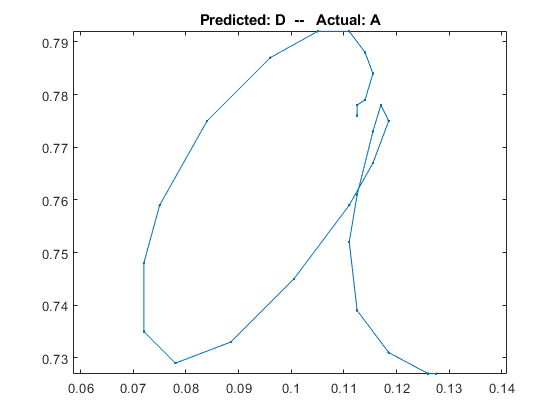

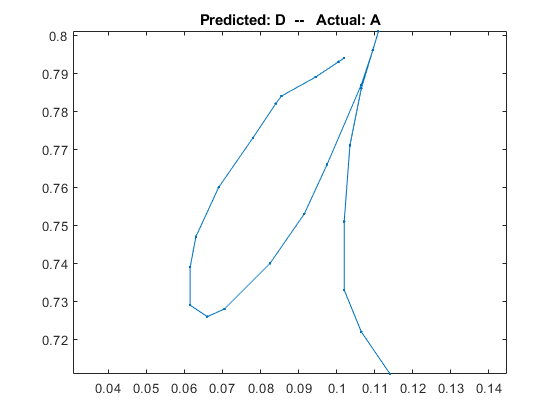

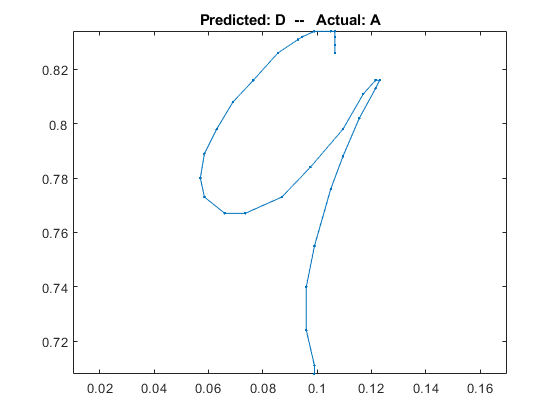

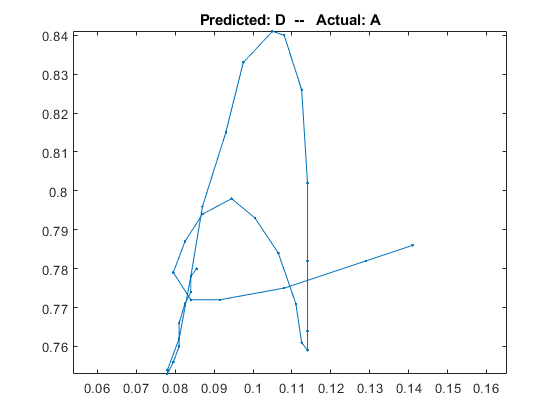

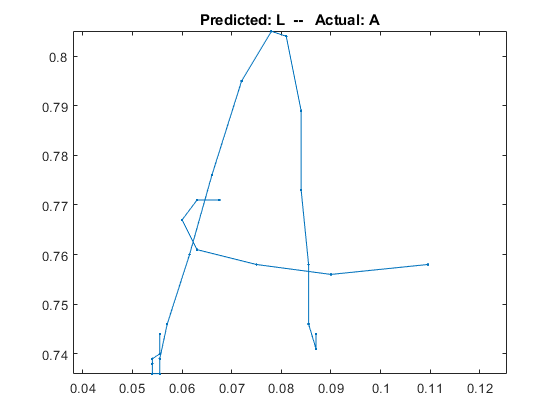

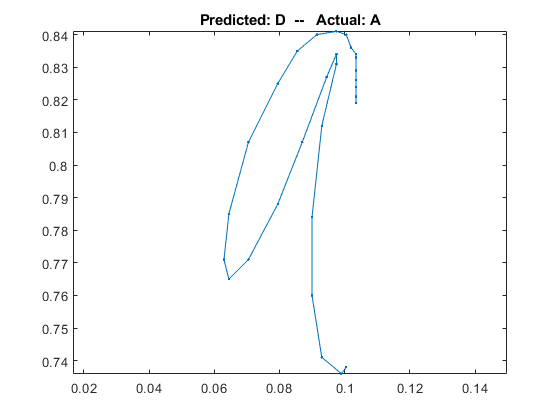

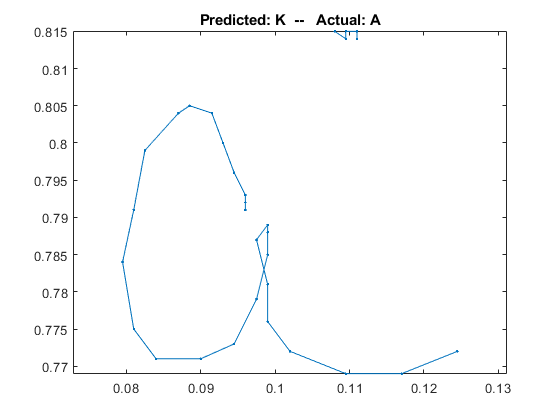

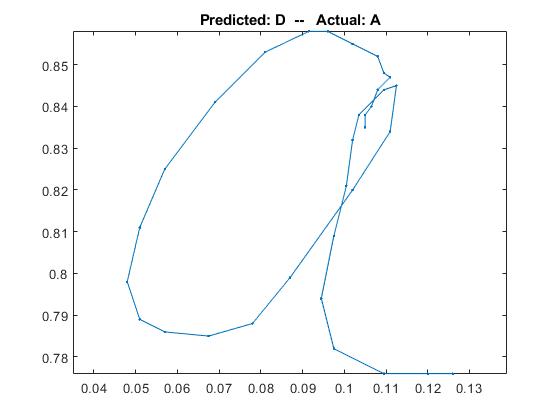

badfiles = testfiles(misclassidx);
for k = 1:numel(badfiles)
    badletter = readtable("C:\Users\Gbadessi\Downloads\machinelearning_course_files\Data"+filesep+badfiles(k));
    figure
    plot(1.5*badletter.X,badletter.Y,".-")
    title("Predicted: "+string(badpred.Prediction(k))+"  --   Actual: "+letter)
    axis equal
end